## **Hard Decision Decoding**


%encoding functions

function y = mul_sh(x, k)
    if k == -1
        y = zeros(1, length(x));
    else
        y = [x(k+1:end) x(1:k)];
    end
end


function [B,H,z] = nrldpc_Hmatrix(BG)
    load(sprintf('%s.txt',BG),BG);
    B = NR_2_6_52;
    [mb,nb] = size(B);
    z = 52;
    H = zeros(mb*z,nb*z); 
    Iz = eye(z); I0 = zeros(z);
    for kk = 1:mb
        tmpvecR = (kk-1)*z+(1:z);
        for kk1 = 1:nb
            tmpvecC = (kk1-1)*z+(1:z);
            if B(kk,kk1) == -1
                H(tmpvecR,tmpvecC) = I0;
            else
                H(tmpvecR,tmpvecC) = circshift(Iz,-B(kk,kk1));
            end
        end
    end
    
    [U,N]=size(H); K = N-U;
    P = H(:,1:K);
    G = [eye(K); P];
    Z = H*G;
end

function cword = nrldpc_encode(B,z,msg)
    %B: base matrix
    %z: expansion factor
    %msg: message vector their length = (#cols(B)-#rows(B))*z
    %cword: codeword vector their length = (#cols(B))*z
    
    [m,n] = size(B);
    
    cword = zeros(1,n*z);
    cword(1:(n-m)*z) = msg;
    
    %double-diagonal structure 
    temp = zeros(1,z);
    %row 1 to 4
    for i = 1:4
        %message columns
        for j = 1:n-m 
            temp = mod(temp + mul_sh(msg((j-1)*z+1:j*z),B(i,j)),2);
        end
    end
    if B(2,n-m+1) == -1
        p1_sh = B(3,n-m+1);
    else
        p1_sh = B(2,n-m+1);
    end
    cword((n-m)*z+1:(n-m+1)*z) = mul_sh(temp,z-p1_sh); %p1

    %Find p2, p3, p4
    for i = 1:3
        temp = zeros(1,z);
        for j = 1:n-m+i
            temp = mod(temp + mul_sh(cword((j-1)*z+1:j*z),B(i,j)),2);
        end
        cword((n-m+i)*z+1:(n-m+i+1)*z) = temp;
    end

    %Remaining parities
    for i = 5:m
        temp = zeros(1,z);
        for j = 1:n-m+4
            temp = mod(temp + mul_sh(cword((j-1)*z+1:j*z),B(i,j)),2);        
        end
        cword((n-m+i-1)*z+1:(n-m+i)*z) = temp;    
    end
end

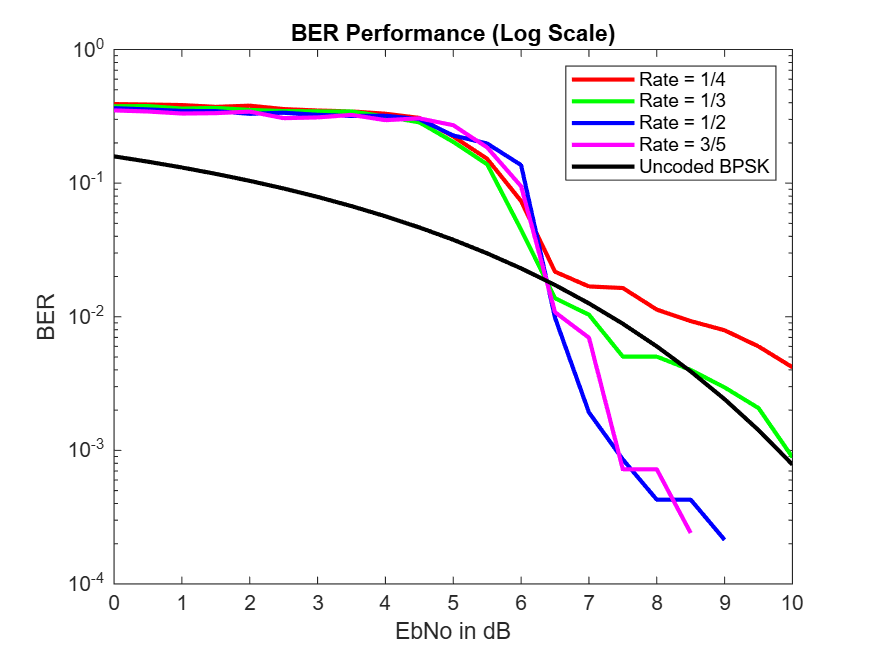

baseGraph5GNR = 'NR_2_6_52'; % Load 5G base H matrix
Nsim = 500;
max_itr = 20;
FlagMatrix = zeros(Nsim, max_itr);
colors = ['r', 'g', 'b', 'm'];

EbNodB = 0:0.5:10;
ErrorProb = zeros(1, length(EbNodB));
R = [1/4 1/3 1/2 3/5];

BER = zeros(length(R), length(EbNodB));

% Storage for graph plot of Error Probability vs Eb/No(dB)
p_error = zeros(length(R), length(EbNodB));

% Storage for graph plot of Success Probabilty vs No of Iteration
p_success_itr = zeros(length(EbNodB), max_itr);

ind_cr = 1;

for codeRate = R 

    % AWGN Channel

    [B, Hfull, z] = nrldpc_Hmatrix(baseGraph5GNR);
    [mb, nb] = size(B);
    kb = nb - mb;
    kNumInfoBits = kb * z;
    k_pc = kb - 2;
    nbRM = ceil(k_pc / codeRate) + 2;
    nBlockLength = nbRM * z;
    
    H = Hfull(:, 1:nBlockLength);
    nChecksNotPunctured = mb*z - nb*z + nBlockLength;
    H = H(1:nChecksNotPunctured, :);
    
    Nchecks = size(H, 1);
        
    
    Rows = size(H, 1);
    Cols = size(H, 2);

    ebno_itr=1;
    
    for EbNoindex = 1:length(EbNodB)

        EbNo = 10^(EbNodB(EbNoindex) / 10);
        sigma = sqrt(1 / (2 * codeRate * EbNo));
        ErrorinBits = 0;

        for ksim = 1:Nsim
            b = randi([0 1], [kNumInfoBits 1]);
            c = nrldpc_encode(B, z, b');
            c = c(1:nBlockLength)';

            % BPSK Modulation
            s = 1 - 2*c;

            rec_vec = s + sigma * randn(size(s));
            rec_vec = (rec_vec < 0);

            M = zeros(Rows, Cols);  % Variable-to-Check message
            L = zeros(Rows, Cols);  % Check-to-Variable message
            decoded_msg = zeros(1, Cols);

            % Initialize messages from variable nodes to check nodes
            for ic = 1 : Cols
                connected_checks = find(H(:, ic));
                for j = 1 : length(connected_checks)
                    M(connected_checks(j), ic) = rec_vec(ic);  % Initial message is received bit
                end
            end

            % Begin decoding iterations
            for itr = 1 : max_itr

                % Check node update (SPC encoding)
                for ir = 1 : Rows
                    connected_vars = find(H(ir, :));
                    for j = 1 : length(connected_vars)
                        others = M(ir, connected_vars([1:j-1, j+1:end]));
                        L(ir, connected_vars(j)) = mod(sum(others), 2);  % Parity excluding self
                    end
                end

                % Variable node update (Majority Voting Algorithim)
                for ic = 1 : Cols
                    connected_checks = find(H(:, ic));
                    total_vote = sum(L(connected_checks, ic)) + rec_vec(ic);
                    decoded_msg(ic) = total_vote > ((length(connected_checks) + 1) / 2);

                    for j = 1 : length(connected_checks)
                        other_votes = L(connected_checks([1:j-1, j+1:end]), ic);
                        cnt = sum(other_votes) + rec_vec(ic);
                        M(connected_checks(j), ic) = cnt > (length(connected_checks) / 2);
                    end
                end

                % early stopping
                % if decoded_msg == prev_decoded_msg
                %     break;
                % end
                % prev_decoded_msg = decoded_msg;

                if (isequal(decoded_msg(:), c(:)) && ind_cr==2)
                    p_success_itr(ebno_itr,itr) = p_success_itr(ebno_itr,itr) + 1;
                end

             end

            % Count bit errors
            bitError = sum(decoded_msg(:) ~= c(:));
            if(bitError > 0)
                BER(ind_cr, ebno_itr) = BER(ind_cr, ebno_itr) + bitError;
                p_error(ind_cr, ebno_itr) = p_error(ind_cr, ebno_itr) + 1;
            end
        end
        BER(ind_cr, ebno_itr) = BER(ind_cr, ebno_itr) / Cols / Nsim;
        p_error(ind_cr, ebno_itr) = p_error(ind_cr, ebno_itr) / Nsim;

        ebno_itr=ebno_itr+1;
    end
    ind_cr=ind_cr+1;
end

p_success_itr = p_success_itr/Nsim;

EbNo = 10 .^ (EbNodB ./ 10);

% Calculate Bit Error Rate (BER) for each SNR
ber_uncoded = 0.5 * erfc(sqrt(EbNo ./ 2));

figure;
for idx = 1:length(R)
    semilogy(EbNodB, BER(idx, :),'Color', colors(idx), 'LineWidth', 2);
    hold on;
end
semilogy(EbNodB, ber_uncoded,'Color','k', 'LineWidth', 2);
xlabel('EbNo in dB');
ylabel('BER');
title('BER Performance (Log Scale)');
legend('Rate = 1/4', 'Rate = 1/3', 'Rate = 1/2', 'Rate = 3/5','Uncoded BPSK');
hold off;

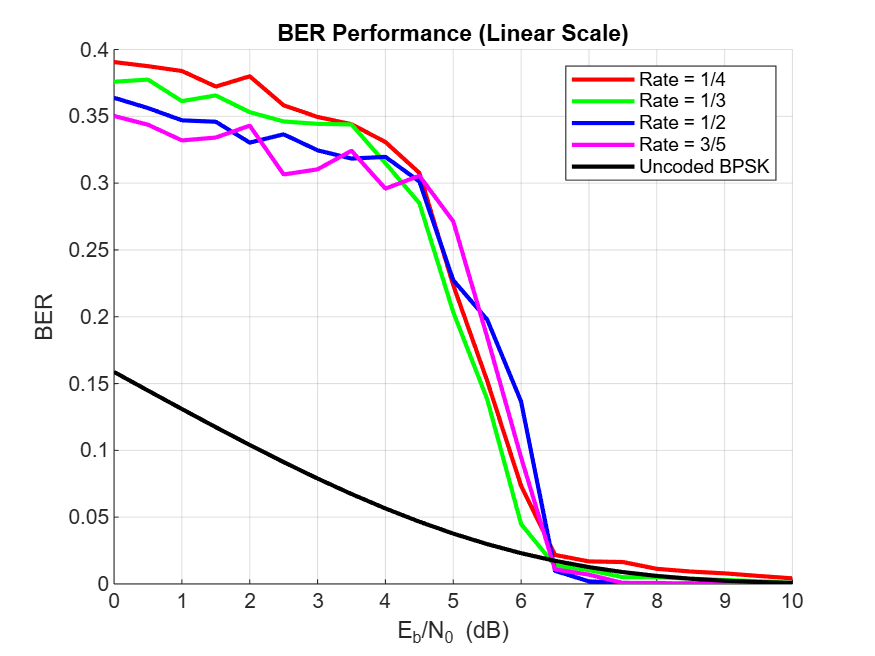


figure;
hold on;
grid on;
for idx = 1:length(R)
    plot(EbNodB, BER(idx, :), 'Color', colors(idx), 'LineWidth', 2);
end
plot(EbNodB, ber_uncoded,'Color','k', 'LineWidth', 2);
xlabel('E_b/N_0 (dB)');
ylabel('BER');
title('BER Performance (Linear Scale)');
legend('Rate = 1/4', 'Rate = 1/3', 'Rate = 1/2', 'Rate = 3/5', 'Uncoded BPSK');
hold off;

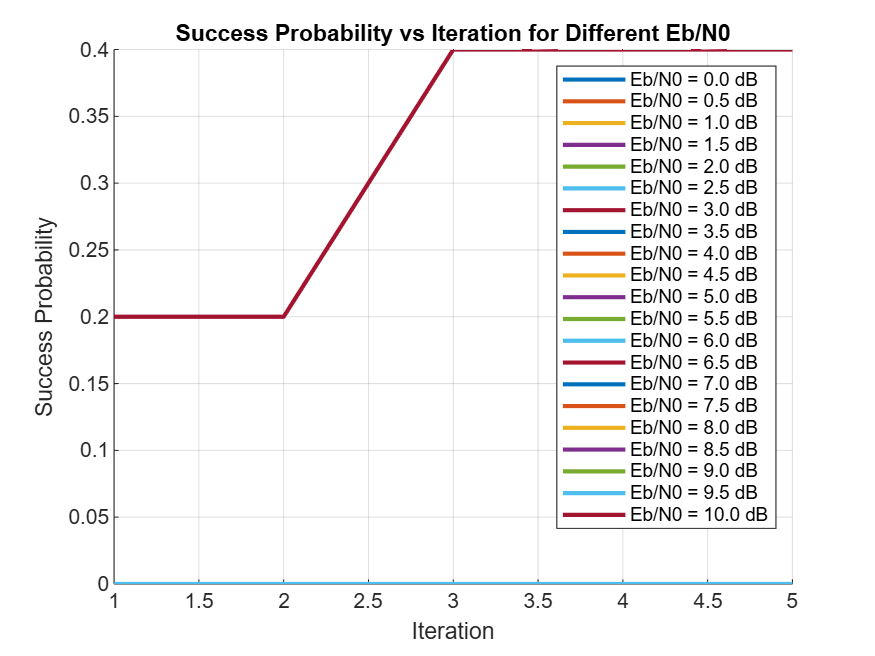


figure;
hold on;
legendEntries = cell(1, length(EbNodB));
for i=1:length(EbNodB)
    plot(1:max_itr,p_success_itr(i,:),'LineWidth',2);
    legendEntries{i} = sprintf('Eb/N0 = %.1f dB', EbNodB(i));
end
xlabel('Iteration');
ylabel('Success Probability');
title('Success Probability vs Iteration for Different Eb/N0');
legend(legendEntries, 'Location', 'northeast');
grid on;
hold off;

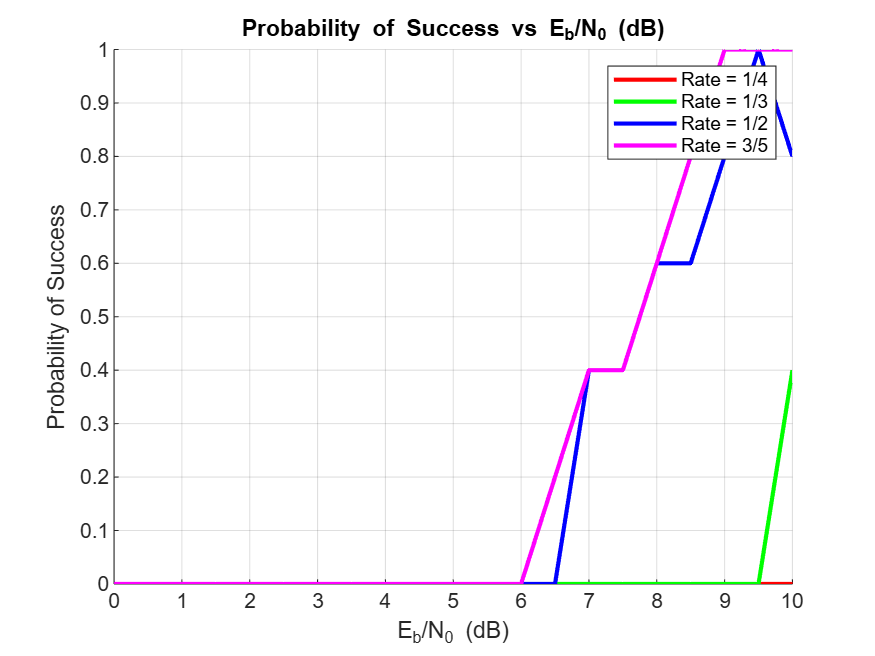


figure;
hold on;
grid on;
for idx = 1:length(R)
    plot(EbNodB, 1-p_error(idx, :), 'Color', colors(idx), 'LineWidth', 2);
end
xlabel('E_b/N_0 (dB)');
ylabel('Probability of Success');
title('Probability of Success vs E_b/N_0 (dB)');
legend('Rate = 1/4', 'Rate = 1/3', 'Rate = 1/2', 'Rate = 3/5');
hold off;

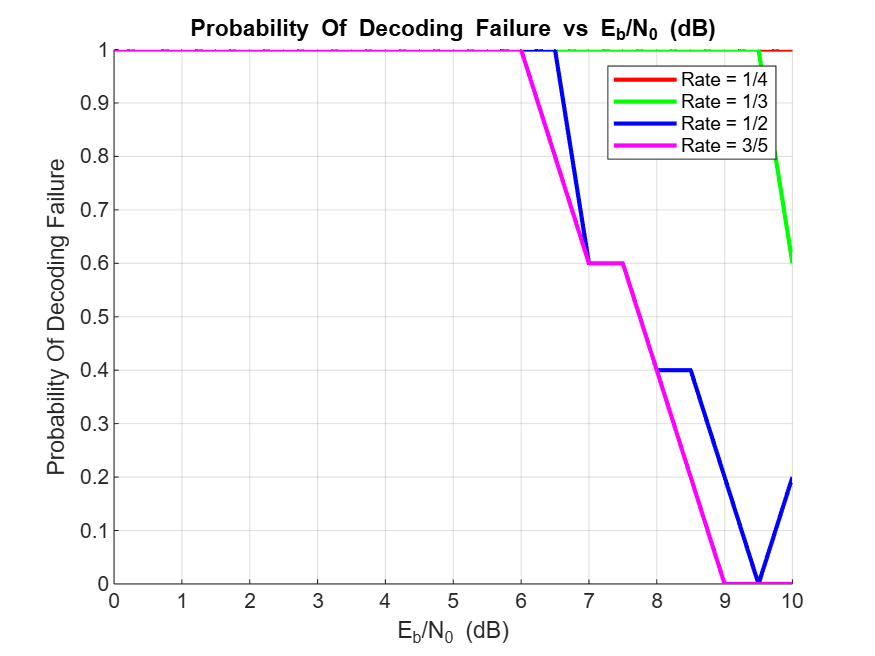


figure;
hold on;
grid on;
for idx = 1:length(R)
    plot(EbNodB, p_error(idx, :), 'Color', colors(idx), 'LineWidth', 2);
end
xlabel('E_b/N_0 (dB)');
ylabel('Probability Of Decoding Failure');
title('Probability Of Decoding Failure vs E_b/N_0 (dB)');
legend('Rate = 1/4', 'Rate = 1/3', 'Rate = 1/2', 'Rate = 3/5');
hold off;